# **Projection to Latent Correlative Structures - Soft discriminant analysis**

## 1. Introduction

Notes: The path of the folders downloaded from GitHub should be [added to the Matlab path](https://www.mathworks.com/help/matlab/matlab_env/add-remove-or-reorder-folders-on-the-search-path.html). 

### 1.1. Loading of the data. 

Test data can be obtained from Zenodo (doi: ) or you can use your own data. In this case, the data structure should have the following architecture:   

    Data.Data: matric [n, m], the data matrix. Spectra are in line, all spectra have the same abscissa (x axis). Data.Wavelength: vector [1, m]. The abscissa.

    Data.Name (Optional). The name of the sample.

    Data.Tag: vector [n, 1], the labelling of the samples with integers (1, 2...k)

    Data.Label4Tag {k}, the names of the label

clear
close all
load('FTIRATR_Pulse.mat')

### 1.2. Preparation of the data

Data can be smooth and the derivatives calculated using the savitzky golay filtering.

% Derivatives
ordSG = 2;  % Order of the SG filter, should be less than wdwSG and more than or equal to deriv
wdwSG = 9; % Window size in which the filter is applied, should be an odd number
deriv = 2;  % Derivative: 0: no derivative, 1: 1st derivatice, 2: 2nd derivative...
               
dt  = mean(Data.Wavelength(1:end-1) - Data.Wavelength(2:end));
Data_old = Data;
[b,g] = sgolay(ordSG, wdwSG);
clear dx
for ii = 1:size(Data.Data, 1)
    x = Data.Data(ii, :);
    dx(ii, :) = conv(x, factorial(deriv)/(-dt)^deriv * g(:,deriv+1), "valid");
    
end
Data.Data = dx;
Wv2Rem = floor(size(Data.Wavelength, 2) - size(Data.Data, 2))/2;
Data.Wavelength = Data.Wavelength(Wv2Rem+1:end-Wv2Rem);
Data.sgolay = [deriv, ordSG, wdwSG];

clear ordSG wdwSG deriv dt b g ii x dx Wv2Rem

## 3. Soft discriminant analysis - 1

Soft discriminant analysis will first be done using the two first principal component latant variables, expressing 69% of the variance.

### 3.1. Cross validation, training and test dataset

%% Cross validation with 25% of the data hold out.
Alfa4SoftDA = 0.05;

p = 0.25;
c = cvpartition(Data.Tag,'Holdout',p);

TrainMe = Data;
TrainMe.Data = Data.Data(c.training, :);
TrainMe.Tag = Data.Tag(c.training);

TestMe = Data;
TestMe.Data = Data.Data(c.test, :);
TestMe.Tag = Data.Tag(c.test);

%% References axis
TagMe = unique(TrainMe.Tag);
Ref.Data = [];
for ii = 1:length(TagMe)
    idData = TrainMe.Data(TrainMe.Tag == TagMe(ii), :);
    Pearson = pdist2(mean(idData, 1), idData, 'correlation');
    Ref.Data(end+1, :) = mean(idData(~isoutlier(Pearson), :), 1);
end
Ref.name = TrainMe.Label4Tag;
PosAxis = [];
for ii = 1:length(TagMe)
    for jj = ii+1:length(TagMe)
        PosAxis(end+1, :) = [ii jj];
    end
end
Ref.LabelAlfa = PosAxis;


%% Calculation of Xpc, the PCA latent axis
[TrainMe.alfa, RefCombination] = PLCS_proj(TrainMe.Data', Ref.Data');
[TestMe.alfa, RefCombination] = PLCS_proj(TestMe.Data', Ref.Data');


%% Model for the discriminat analysis
X = TrainMe.alfa(:, [2, 5]); % Two first pcs
Mdl = fitcdiscr(X,  TrainMe.Tag, 'DiscrimType', "quadratic");

### 3.2. Optimisation of the DA model

#### 3.2.1. Visualisation of the clusters

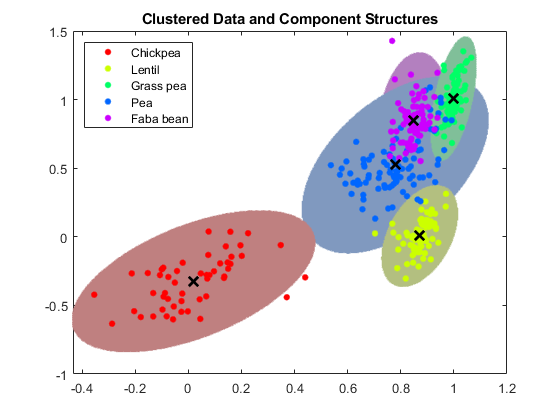

d = 500;


figure;
h1 = gscatter(X(:,1), X(:,2), TrainMe.Tag);
XL = xlim;
YL = ylim;
x1 = linspace(XL(1), XL(2), d);
x2 = linspace(YL(1), YL(2), d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];
mahalDist = mahal(Mdl, X0);

hold on;
for jj = 1:5
    v = sum(TrainMe.Tag == jj) - 1;
    SoftClustThre = sqrt(chi2inv(1-Alfa4SoftDA, v));
    idx = mahalDist(:,jj)<=SoftClustThre;
    Color = h1(jj).Color*0.75 + -0.5*(h1(jj).Color - 1);
    h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
    uistack(h2,'bottom');
end
h3 = plot(Mdl.Mu(:,1), Mdl.Mu(:,2),'kx','LineWidth',2,'MarkerSize',10);
title('Clustered Data and Component Structures');
legend(h1,Data.Label4Tag,'Location','NorthWest');
hold off

#### 3.2.2.  Find and remove outliers

Outliers are defined as the samples that are at a Mahalanobis distance greater than 3 from the center of the cluster to witch they belong. Outliers are removed and the DA model recalculated without those.

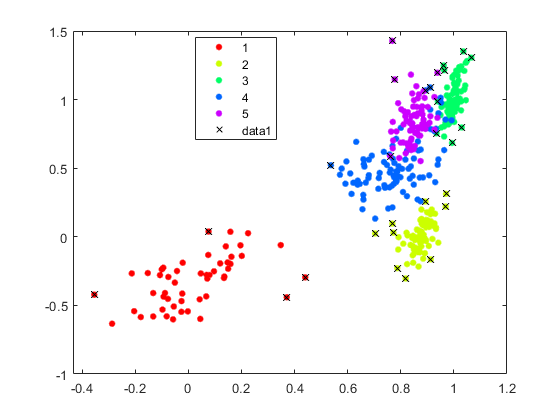

% Visualisation of the clusters
mahalDist =  mahal(Mdl, X);
ido = false(size(TrainMe.Tag));
for jj = 1:5
    tgt = find(TrainMe.Tag==jj) ;
    ido(tgt(isoutlier(mahalDist(tgt,jj)))) = true;
end

X_rob = X(~ido, :);
Y_rob = TrainMe.Tag(~ido);
Mdl_rob = fitcdiscr(X_rob,  Y_rob, 'DiscrimType', "quadratic");

d = 1000;
figure;
nexttile
h1 = gscatter(X(:,1), X(:,2), TrainMe.Tag);
hold on
scatter(X(ido, 1), X(ido, 2), "xk", "SizeData", 50)
hold off


XL = xlim;
YL = ylim;
x1 = linspace(XL(1), XL(2), d);
x2 = linspace(YL(1), YL(2), d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];
mahalDist = mahal(Mdl, X0);

hold on;
for jj = 1:5
    v = sum(Y_rob == jj) - 1;
    SoftClustDA = sqrt(chi2inv(1-Alfa4SoftDA, v));
    idx = mahalDist(:,jj)<=SoftClustDA;
    Color = h1(jj).Color*0.75 + -0.5*(h1(jj).Color - 1);
    h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
    uistack(h2,'bottom');
end
title('Classified Data and Component Structures');
Lgd = Data.Label4Tag;
h = legend(h1, Lgd,'Location','NorthWest');
idlbl = RefCombination(2, :);
xlabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])
idlbl = RefCombination(5, :);
ylabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])
hold off
XL = xlim;
YL = ylim;

nexttile
mahalDist = mahal(Mdl_rob, X0);
hold on;
listThres = [];
for jj = 1:5
    v = sum(Y_rob == jj) - 1;
    SoftClustDA = sqrt(chi2inv(1-Alfa4SoftDA, v));
    listThres(end+1) = SoftClustDA;
    idx = mahalDist(:,jj) <= SoftClustDA;
    Color = h1(jj).Color*0.75 + -0.5*(h1(jj).Color - 1);
    h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',3);
    uistack(h2,'bottom');
end
mahalDist = mahalDist./listThres;
idx = sum(mahalDist <= 1, 2) > 1;
Color = [0.5 0.5 0.5];
h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',3);
title('Component Structures');
    
h3 = plot(Mdl_rob.Mu(:,1), Mdl_rob.Mu(:,2),'kx','LineWidth',2);
hold off
xlim(XL);
ylim(YL);
idlbl = RefCombination(2, :);
xlabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])
idlbl = RefCombination(5, :);
ylabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])

### 3.3. Validation

figure
nexttile
% hard correlation
ypred = predict(Mdl_rob, TestMe.alfa(:, [1:2]));
cm = confusionchart(Data.Label4Tag(TestMe.Tag), Data.Label4Tag(ypred));
title("Hard classification")

% soft correlation
mahalDist = mahal(Mdl_rob, TestMe.alfa(:, [1:2]));
mahalDist = mahalDist./listThres;
[~, YHat] = min(mahalDist, [], 2); %smalles Mah Dist
YHat(sum(mahalDist < 1, 2) == 0) = 6; % not classified with d^2 <= 3;
YHat(sum(mahalDist < 1, 2) > 1) = 7; % multiple classification;
Lgd = Data.Label4Tag;
Lgd{end+1} = 'unclassified';
Lgd{end+1} = 'multinomial classification';
nexttile
cm = confusionchart(Lgd(TestMe.Tag), Lgd(YHat));
title("Soft classification")

clear ordSG wdwSG deriv dt b g ii x dx Wv2Rem p
clear ClustersResolution Color d f h h1 h2 h3 icons ido idx ii j jj Lgd mahalDist Mdl prov tgt X
clear X0  x1 x1grid x2 x2grid XL Yl ypred cm YPhat

## 4. Optimisation of the selection of axis

The function **OptAxis4fitcdiscr(XTest, XTrain, YTest, YTrain, nbrAxis, DiscrimType) **does the same steps as in 3, but the input Data can have more than two variables (here PCs). **OptAxis4fitcdiscr **will test all the combination of variables in the discriminant analysis, nbrAxis is the number of variables that will be used in the DA (2 to 5), Y is the data label (encoded as numerical values) and DiscrimType is the type of analysis (see the Matlab function [fitcdiscr](https://www.mathworks.com/help/stats/fitcdiscr.html) for more information, we recomand "quadratic"as discriminant type). We recomand to use between 10 and 25 variables in the input Data (for reason of computing speed as all possible combination will be tested).

**4.1. Preparation of data**

%% Model for the discriminat analysis
Results  = OptAxis4fitcdiscr(TrainMe.alfa, TrainMe.Tag, TestMe.alfa, TestMe.Tag, 2, "quadratic");

### 4.2. Selection of best model

ID = find(Results.n_soft == max(Results.n_soft)); ID = ID(1);
AxisCmb = Results.AxisComb{ID}
disp(Results(ID, :))
Mdl = Results.DAModel{ID};

d = 500;

figure;
nexttile
h1 = gscatter(TrainMe.alfa(:,AxisCmb(1)), TrainMe.alfa(:,AxisCmb(2)), TrainMe.Tag);
XL = xlim;
YL = ylim;
x1 = linspace(XL(1), XL(2), d);
x2 = linspace(YL(1), YL(2), d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];
mahalDist = mahal(Mdl, X0);
legend(h1,TrainMe.Label4Tag,'Location','NorthWest');
threshold = Results.ThresSoftDA{ID};
mahalDist = mahalDist./threshold;
idlbl = RefCombination(AxisCmb(1), :);
title('Classified Data and Component Structures');
xlabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])
idlbl = RefCombination(AxisCmb(2), :);
ylabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])

nexttile
hold on;
for jj = 1:5
    idx = mahalDist(:,jj)<= 1;
    Color = h1(jj).Color*0.75 + -0.5*(h1(jj).Color - 1);
    h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',3);
    uistack(h2,'bottom');
end
idx = sum(mahalDist<= 1, 2) > 1;
Color = [0.5 0.5 0.5];
h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',3);
title('Component Structures');
idlbl = RefCombination(AxisCmb(1), :);
xlabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])
idlbl = RefCombination(AxisCmb(2), :);
ylabel([Data.Label4Tag{idlbl(1)} ' <=> ' Data.Label4Tag{idlbl(2)}])
h3 = plot(Mdl.Mu(:,1), Mdl.Mu(:,2),'kx','LineWidth',2);
hold off
xlim(XL);
ylim(YL);

figure
nexttile
% hard correlation
cm = Results.HardConfMatrix{ID};
confusionchart(cm, Data.Label4Tag);
title("Hard classification")

% soft correlation
cm = Results.SoftConfMatrix{ID};
Lgd = Data.Label4Tag;

if  any(Results.TagsInC_soft{ID} == 6)
    Lgd{end+1} = 'unclassified';
end

if any(Results.TagsInC_soft{ID} == 7)
    Lgd{end+1} = 'multinomial classification';
end
nexttile
confusionchart(cm, Lgd);
title("Soft classification")

clear ordSG wdwSG deriv dt b g ii x dx Wv2Rem p
clear ClustersResolution Color d f h h1 h2 h3 icons ido idx ii j jj Lgd mahalDist Mdl prov tgt X
clear X0  x1 x1grid x2 x2grid XL Yl ypred cm YPhat

## 5. Higher dimension hard and soft classification

### 5.1. Three dimensional DA

Results  = OptAxis4fitcdiscr(TrainMe.alfa, TrainMe.Tag, TestMe.alfa, TestMe.Tag, 3, "quadratic");
ID = find(Results.n_soft == max(Results.n_soft)); ID = ID(1);
AxisCmb = Results.AxisComb{ID}
disp(Results(ID, :))
Mdl = Results.DAModel{ID};


figure
nexttile
% hard correlation
cm = Results.HardConfMatrix{ID};
confusionchart(cm, Data.Label4Tag);
title("Hard classification")

% soft correlation
cm = Results.SoftConfMatrix{ID};
Lgd = Data.Label4Tag;
if  any(Results.TagsInC_soft{ID} == 6)
    Lgd{end+1} = 'unclassified';
end

if any(Results.TagsInC_soft{ID} == 7)
    Lgd{end+1} = 'multinomial classification';
end
nexttile
confusionchart(cm, Lgd);
title("Soft classification")

### 5.2. 4th dimensional DA

Xpc = TrainMe.alfa(:, 1:10);
Results  = OptAxis4fitcdiscr(Xpc, TrainMe.Tag, TestMe.alfa(:, 1:10), TestMe.Tag, 4, "quadratic");
ID = find(Results.n_soft == max(Results.n_soft)); ID = ID(1);
AxisCmb = Results.AxisComb{ID}
disp(Results(ID, :))
Mdl = Results.DAModel{ID};


figure
nexttile
% hard correlation
cm = Results.HardConfMatrix{ID};
confusionchart(cm, Data.Label4Tag);
title("Hard classification")

% soft correlation
cm = Results.SoftConfMatrix{ID};
Lgd = Data.Label4Tag;
if  any(Results.TagsInC_soft{ID} == 6)
    Lgd{end+1} = 'unclassified';
end

if any(Results.TagsInC_soft{ID} == 7)
    Lgd{end+1} = 'multinomial classification';
end
nexttile
confusionchart(cm, Lgd);
title("Soft classification")

### 5.3. 5th dimensional DA